## Fourier Analysis

### [**Hiroyuki Chihara**](https://fiomfd.github.io/)** (University of the Ryukyus, Okinawa Island, Japan)**

**Fourier series**

- Definition of Fourier series

- Real Form of the Fourier series

- Example of Fourier series

- Dirichelet kernel

- Fourier series of periodic continuous functions

- Fourier series of triangular function

- A continuous function whose fourier series does not converges even pointwisely

- Step function and sawtooth function

- Decomposition of piecewise smooth functions

- Weyl's equidistribution theorem

- Continuous but nowhere differentiable functions

**Fourier Series and Fourier transform**

        12. Shannon's sampling theorem and aliasing

## 1. Definition of Fourier Series

Throughout this note we consider piecewise continuous $1$-periodic functions $f(x)$ on $\mathbb{R}$, that is, 

- $f(x+1)=f(x)$ for all $x\in\mathbb{R}$.

- There exist numbers $0=a_0<a_1<\cdots<a_m=1$ such that $f(x)$ is continuous on each open interval $(a_{j-1},a_j)$, $j=1,\ldots,m$, and limits exist:


$$f(a_0+0), 
\quad
f(a_1-0),
\quad
f(a_1+0),
\quad
\ldots
\quad
f(a_m-0).$$


We remark that if we restrict $f(x)$ on each closed interval $[a_{j-1}+k,a_j+k]$ for $j=1,\ldots,m$ and $k\in\mathbb{Z}$, $f(x)$ can be regarded as a continuous function. We denote by $\mathcal{L}$ the set of all piecewise continuous $1$-periodic functions on $\mathbb{R}$. 

All the $e^{2\pi i n x}$, $n \in \mathbb{Z}$ are $1$-periodic smooth functions. In the spirit of Joseph Fourier (1768-1830), we consider whether $f(x) \in \mathcal{L}$ can be expressed by a trigonometric series of the form


$$\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}.$$


If $f(x)
=
\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}$ holds, then we have by formal computation 


$$\int_0^1
f(x)e^{-2\pi i mx}
dx
=
\int_0^1
\sum_{n=-\infty}^{\infty}
c_n
e^{2\pi i(n-m)x}
dx
=
\sum_{n=-\infty}^\infty
c_n
\int_0^1
e^{2\pi i (n-m)x}
dx
=
\sum_{n=-\infty}^\infty
c_n\delta_{mn}
=
c_m.$$


Note that the condition $f(x) \in \mathcal{L}$ guarantees the existence of the left hand side of the above. The formal trigonometric series defined by 


$$\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}, 
\quad
c_n
=
\int_0^1
f(x)e^{-2\pi i nx}
dx$$


is said to be the Fourier series of $f(x)$, and we denote this by 


$$f(x)
\sim
\sum_{n=-\infty}^\infty
c_n
e^{2\pi i nx}.$$


$c_n$ is called the $n$-th Fourier coefficient of $f(x)$.

## 2. Real Form of the Fourier Series

If $f(x)$ is real valued, then the Fourier series can be written by the real-valued trigonometric series. In this case $\overline{c_{-n}}=c_n$ holds, and $c_0$ is a real number. If we set for $n=0,1,2,\ldots$


$$\overline{c_n}=c_{-n}
=
\frac{a_n+ib_n}{2}, 
\quad
a_n
=
2
\int_0^1
f(x)
\cos(2\pi nx)
dx,
\quad
b_n
=
2
\int_0^1
f(x)
\sin(2\pi nx)
dx,$$


then $b_0=0$, and 


$$f(x)
\sim
\frac{a_0}{2}
+
\sum_{n=1}^\infty
\bigl(
a_n\cos(2\pi nx)
+
b_n\sin(2\pi nx)
\bigr).$$


It is convenient to compute 


$$\frac{a_0}{2}
=
c_0
=
\int_0^1f(x)dx,$$



$$a_n+ib_n
=
2c_{-n}
=
2
\int_0^1
f(x)e^{2\pi i nx}
dx, 
\quad
n=1,2,3,\ldots.$$


For $\lambda=\mu+i\nu \in \mathbb{C}, 
\quad
\mu,\nu \in \mathbb{R}$, we have 


$$e^{\lambda x}
=
e^{\mu x + i\nu x}
=
e^{\mu x}
\{\cos(\nu x)+i\sin(\nu x)\},$$



$$\frac{d}{dx}e^{\lambda x}
=
\frac{d}{dx}
\bigl[
e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
\bigr]$$



$$\qquad
=
\mu e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
+
\nu
e^{\mu x}
\{-\sin(\nu x) + i\cos(\nu x)\}$$



$$\qquad
=
\mu e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
+
i\nu
e^{\mu x}
\{i\sin(\nu x) + \cos(\nu x)\}$$



$$\qquad
=
(\mu + i\nu)
e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
=
\lambda e^{\lambda x},$$


which is useful for computing Fourier coefficients. 

## 3. Example of Fourier Series

 Let $f(x)$ be a function defined by 


$$f(x) 
:= 
\min\{x-[x],1-x-[1-x]\},
\quad
x\in\mathbb{R},$$



$$\lfloor{s}\rfloor:=\max\{m \in \mathbb{Z} :  m \leq s\}, 
\quad
s\in\mathbb{R}.$$


In other words, $f(x)$ is a $1$-periodic Lipshitz continuous function such that 


$$f(x)
=
\cases{x, &\quad x\in[0,1/2), \cr 1-x, &\quad x\in[1/2,1).}$$
 

We shall confirm that the Fourier series of $f(x)$ is  


$$f(x)
\sim
\frac{1}{4}
-
\sum_{k=1}^\infty
\frac{2}{(2k-1)^2\pi^2}
\cos\bigl(2(2k-1)\pi x\bigr).$$


Indeed


$$\frac{a_0}{2}
=
\int_0^{1/2}xdx
+
\int_{1/2}^1(1-x)dx
=
\frac{2}{2^3}
=
\frac{1}{4},$$


and for $n=1,2,3,\dots,$


$$a_n+ib_n
=
2\int_0^{1/2}
xe^{2\pi i nx}
dx
+
2\int_{1/2}^1
(1-x)e^{2\pi i nx}
dx$$



$$\qquad
=
\left[
\frac{xe^{2\pi i nx}}{n\pi i}
\right]_0^{1/2}
+
\left[
\frac{(1-x)e^{2\pi i nx}}{n\pi i}
\right]_{1/2}^1
-
\int_0^{1/2}
\frac{e^{2\pi i nx}}{n\pi i}
dx
+
\int_{1/2}^1
\frac{e^{2\pi i nx}}{n\pi i}
dx$$



$$\qquad
=
0
-
\left[
\frac{e^{2\pi i nx}}{2(n\pi i)^2}
\right]_0^{1/2}
+
\left[
\frac{e^{2\pi i nx}}{2(n\pi i)^2}
\right]_{1/2}^1
$$



$$\qquad
=
\frac{e^{\pi i n}-1-1+e^{\pi i n}}{2n^2\pi^2}
=
\frac{\cos(n\pi)-1}{n^2\pi^2}
=
-
\frac{1-(-1)^n}{n^2\pi^2}$$



$$\qquad
=
\cases{-\frac{2}{(2k-1)^2\pi^2}, &\quad n=2k-1, \cr 0, &\quad n=2k,}
\quad
k=1,2,3,\ldots.$$


## 4. Dirichelet Kernel

Suppose $f(x) \in \mathcal{L}$ and $f(x)
\sim
\displaystyle\sum_{n=-\infty}^\infty
c_ne^{2\pi i n x}$. Our basic problems are the following.

- **Q1. Does the formal series **$\displaystyle\sum_{n=-\infty}^\infty
c_ne^{2\pi i n x}$** converge?**

- **Q2. If the formal series **$\displaystyle\sum_{n=-\infty}^\infty
c_ne^{2\pi i n x}$** converges, **$f(x)
=
\displaystyle\sum_{n=-\infty}^\infty
c_ne^{2\pi i n x}$** holds?**

We introduce the partial $N$-the sum of the series


$$S_N(x)
:=
\sum_{n=-N}^N
c_ne^{2\pi i nx}. $$


We have 


$$S_N(x)
=
\int_0^1
D_N(x-y)
f(y)
dy
=
\int_{-1/2}^{1/2}
D_N(t)
f(x+t)
dt,$$



$$D_N(t)
=
\sum_{n=-N}^N
e^{2\pi i nt}
=
1
+
2
\sum_{n=1}^N
\cos(2\pi nx)$$


by the definition of the Fourier coefficients. $D_N(t)$ is called the $N$-th Dirichelet kernel. $D_N(t)$ is $1$-periodic smooth function and 


$$\int_0^1D(t)dt=1.$$


Moreover we obtain 


$$D_N(t)
=
\cases{\frac{\sin\bigl(\pi(2N+1)t\bigr)}{\sin(\pi t)}, &\quad t\not\in\mathbb{Z}, \cr 2N+1, &\quad t\in\mathbb{Z}.}$$
 

This expression is useful to study the convergence and divergence of Fourier series. Here we observe the behavior of the Dirichelet kernel in a one-period interval $[-1/2,1/2]$. Roughly speaking 

- **The mass is concentrating on an interval **$I_N:=[-1/(2N+1),1/(2N+1)]$** as **$N \rightarrow \infty$**.**

- $D_N(t)$** oscillates more violently in **$[-1/2,1/2]\setminus{I_N}=[-1/2,-1/(2N+1))\cup(1/(2N+1),1/2]$ **as **$N \rightarrow \infty$**.**

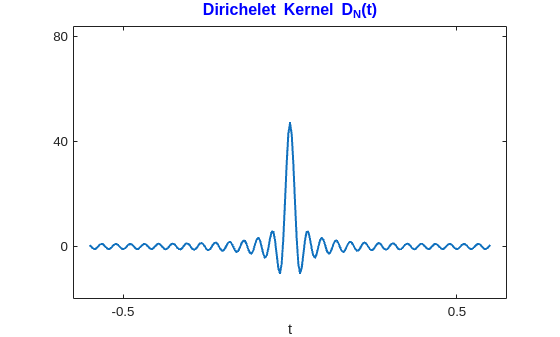

close;
M=40;
N =23;

t = -0.6:0.005:0.6;
S=ones(M+1,241);
for m=2:M+1
    for k=1:241
        S(m,k)=S(m-1,k)+2*cos(2*pi*(m-1)*t(1,k));
    end
end

plot(t,S(N+1,:),'LineWidth',1.5);
   ylim([-M/2 2*M+M/10])
   xlim([-0.65 0.65])
   title('Dirichelet Kernel D_N(t)','Color','blue','FontSize',12)
   xlabel('t')
   xticks([-0.5 0.5])
   yticks([0 M 2*M])

## 5. Fourier Series of Periodic Continuous Functions 

We have the following results on the convergence and divergence of the Fourier series of continuous function. 

- **Suppose that **$f(x)$** is **$1$**-periodic Hoelder continuous of degree **$\alpha \in (0,1]$**, that is, there exists a constant **$L>0$** such that **$|f(x)-f(y)| \leq L|x-y|^\alpha$** for any **$x,y\in\mathbb{R}$**. Then **


$$\max_{x\in[0,1]}
\left|S_N(x)-f(x)\right|
\rightarrow
0
\quad
(N \rightarrow \infty).$$


- **Moreover if **$\alpha>1/2$**, then **


$$\sum_{n=-\infty}^{\infty}
|c_n|
<\infty.$$


- **There exists a is **$1$**-periodic continuous function **$f(x)$** such that **


$$S_N(0) \rightarrow \infty
\quad
(N \rightarrow \infty).$$


Here we have some remarks on Hoelder continuity. The condition $|f(x)-f(y)| \leq L|x-y|^\alpha$ is a restriction only for small $|x-y|$ since the absolute value of a periodic continuous function has a maximum. Roughly speaking, the exponent $\alpha$ expresses that $f(x)$ is differentiable of order $\alpha$. When $\alpha=1$, the Hoelder continuity is said to be the Lipshitz continuity. The Rademach theorem shows that the Lipshitz continuous function is differentiable almost everywhere with respect to the Lebesgue measure on $\mathbb{R}$. Roughly speaking, **Part 1 and Part 3** assert that if $f(x)$ is a little bit smoother than continuous functions, its Fourier series uniformly converges to $f(x)$, and otherwise, its Fourier series does not necessarily converge even pointwisely. 

We show the outline of the proof of** Part 1**. Note that $S_N(x)-f(x)$ can be written as 


$$S_N(x)-f(x)
=
\int_{-1/2}^{1/2}
D_N(t)
\{f(x+t)-f(x)\}
dt.$$


The Hoelder condition implies that for any small $\delta>0$


$$S_N(x)-f(x)
=
\int_{|t|<\delta}
O(|t|^{-1+\alpha})
dt
+
\int_{\delta<|t|<1/2}
\sin\bigl(\pi(2N+1)t\bigr)
\times
\cdots
dt.$$


The second term of the right hand side is vanishing as $N \rightarrow \infty$ due to the oscillation and $\int_0^1\sin(2\pi x)dx=0$. Indeed for any $\varphi(t) \in C^1[0,1]$, 


$$\int_0^1\sin(2\pi Nt)\varphi(t)dt
=
\left[-\frac{\cos(2\pi Nt) \varphi(t)}{2\pi N}\right]_0^1
+
\int_0^1
\frac{\cos(2\pi Nt) \varphi^\prime(t)}{2\pi N}
dt
=
O(N^{-1})
\quad
(N \rightarrow \infty).$$


The differentiability of $\varphi(t)$ is not required for this. In fact one can also prove 


$$\int_0^1\sin(2\pi Nt)\varphi(t)dt
\rightarrow 0
\quad
(N \rightarrow \infty)$$


for $\varphi(t) \in C[0,1]$ by using the uniform continuity of $\varphi(t)$ and $\int_0^1\sin(2\pi x)dx=0$. So we have for any small $\delta>0$


$$S_N(x)-f(x)
=
O(\delta^\alpha)
+
o(1)
\quad
(N \rightarrow 0).$$


## 6. Fourier Series of Triangular Function

Consider a $1$-periodic function $f(x)$ defined by 


$$f(x)
=
\cases{x, &\quad x\in[0,1/2), \cr 1-x, &\quad x\in[1/2,1).}$$


This is the same as the example in Section 3. Here we observe the uniform convergence of the Fourier series of $f(x)$, which is 


$$f(x)
=
\frac{1}{4}
-
\sum_{k=1}^\infty
\frac{2}{(2k-1)^2\pi^2}
\cos\bigl(2(2k-1)\pi x\bigr),$$



$$S^\prime_K[f](x)
=
\frac{1}{4}
-
\sum_{k=1}^K
\frac{2}{(2k-1)^2\pi^2}
\cos\bigl(2(2k-1)\pi x\bigr).$$


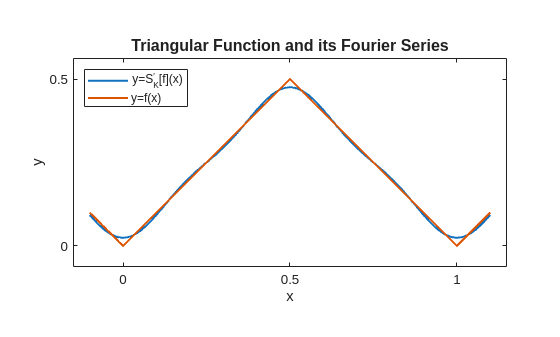

x = -0.1 : 0.005 : 1.1;
f = min(x-floor(x),1-x-floor(1-x));

M1=20;

K =2;
S1=ones(M1+1,length(x))/4;
for k=2:M1+1
    for l=1:length(x)
        S1(k,l)=S1(k-1,l)-2*cos(2*(2*k-3)*pi*x(1,l))/(2*k-3)^2/pi^2;
    end
end

plot(x,S1(K+1,:),x,f,'LineWidth',1.5)
axis equal
ylim([-1/16 9/16])
xlim([-0.15 1.15])
title('Triangular Function and its Fourier Series','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
yticks([0 1/2])
ylabel('y')
legend('y=S^\prime_K[f](x)','y=f(x)','Location','northwest')

## **7. A continuous function whose fourier series does not converges even pointwisely**

Define a function


$$f(x)
=
\sum_{k=1}^\infty
\frac{2}{3^k}
\sin\{2\pi(2k+1)n(k)x\}
\sum_{l=1}^{n(k)}
\frac{\sin(2\pi lx)}{l},$$



$$n(k)=3^{3^k},
\quad\text{i.e.,}\quad
\log{n(k)}=3^k\log{3},$$


which converges uniformly on $\mathbb{R}$, and is a $1$-periodic continuous function. 

Consider its Fourier series and the patrial sum


$$f(x) \sim \sum_{n=-\infty}^\infty C_ne^{2\pi nx}, 
\quad
S_N(x):=\sum_{n=-N}^N C_ne^{2\pi nx}.$$


It is well-known that the sequence $\{S_N(0)\}$ does not converge, more precisely, we have 


$$S_{(2k+1)n(k)}(0)-S_{2kn(k)}(0)
=
\frac{1}{3^k}\sum_{j=1}^{n(k)-1}\frac{1}{j}
>
\log{3}.$$


We tried to see the graph of $f$ by using 


$$f_K(x)
:=
\sum_{k=1}^K
\frac{2}{3^k}
\sin\{2\pi(2k+1)n(k)x\}
\sum_{l=1}^{n(k)}
\frac{\sin(2\pi lx)}{l}.$$


Unfortunately, we could not do it well since 


$$n(1)=9, \quad n(2)=19683, \quad n(3)=7625597484987.$$


We could compute $f_2$, and not $f_3$, and show the graph of $f_3$ below.

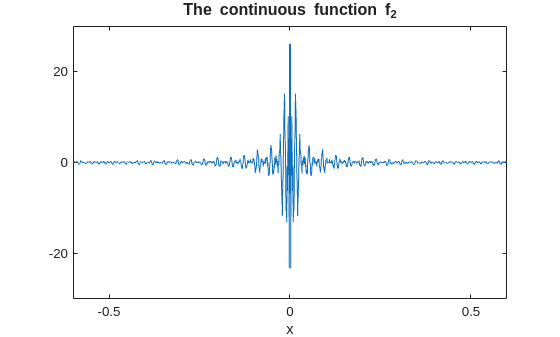

x5 = -0.6: 0.001: 0.6;

f5=zeros(1,length(x5));
for p=1:length(x5)
	for k=1:2
	    g5=0.0;
	 	for l=1:3^(3^k)
	 		g5 = g5+sin(2*pi*l*x5(1,p));
	 	end
	 	f5(1,p) = f5(1,p)+(2/(3^k))*sin(2*pi*(2*k+1)*3^(3^k)*x5(1,p))*g5;
    end
end

plot(x5,f5)
title('The continuous function f_2','FontSize',12)
xlabel('x')
xticks([-0.5 0 0.5])
yticks([-20 0 20])

## 8. Step Function and Sawtooth Function

Let $Y(x)$ be the heaviside function, that is, 


$$Y(x)
=
\cases{1, &\quad x\geq0, \cr 0, &\quad x<0.}$$


The value $Y(0)=1$ does not matter essentially, and is not needed to be defined. Consider a step function $g(x)$ and a sawtooth function $h(x)$ defined by 


$$g(x)
:=
\sum_{k=-\infty}^\infty
Y(x+k){\times}Y(1/2-x-k),
\quad
h(x):=x-[x].$$


They are $1$-periodic function such that for $x\in[0,1)$


$$g(x)
=
\cases{1, &\quad x\in[1,1/2], \cr 0, &\quad x\in (1/2,1),}
\qquad
h(x)=x.
$$


Their Fourier series are 


$$g(x)
\sim
\frac{1}{2}
+
\sum_{k=1}^\infty
\frac{2}{(2k-1)\pi}
\sin\bigl(2(2k-1)\pi x\bigr),$$



$$S^\prime_K[g](x)
=
\frac{1}{2}
+
\sum_{k=1}^K
\frac{2}{(2k-1)\pi}
\sin\bigl(2(2k-1)\pi x\bigr),$$



$$h(x)
\sim
\frac{1}{2}
-
\sum_{n=1}^\infty
\frac{1}{n\pi}
\sin(2n\pi x),$$



$$S_N[h](x)
=
\frac{1}{2}
-
\sum_{n=1}^N
\frac{1}{n\pi}
\sin(2n\pi x).$$


On one hand, at the discontinuous points 


$$S^\prime_K[g](k)
=
\frac{1}{2}
\rightarrow
\frac{1}{2}
=
\frac{g(k-0)+g(k+0)}{2}
\quad
(K \rightarrow \infty),$$



$$S^\prime_K[g](k+1/2)
=
\frac{1}{2}
\rightarrow
\frac{1}{2}
=
\frac{g(k+1/2-0)+g(k+1/2+0)}{2}
\quad
(K \rightarrow \infty),$$



$$S_N[h](k)
=
\frac{1}{2}
\rightarrow
\frac{1}{2}
=
\frac{h(k-0)+h(k+0)}{2}
\quad
(N \rightarrow \infty),$$


for all $k \in \mathbb{Z}$. On the other hand, we can prove that for any small $\delta>0$


$$\max_{x\in[\delta,1/2-\delta]\cup[1/2+\delta,1-\delta]}
|S^\prime_K[g](x)-g(x)|
\rightarrow 0
\quad
(K \rightarrow \infty),$$



$$\max_{x\in[\delta,1-\delta]}
|S_N[h](x)-h(x)|
\rightarrow 0
\quad
(N \rightarrow \infty).$$


The partial sums oscillate violately as $N$ increases near the discontinuous points. This is called the** Gibbs Phenomenon**.

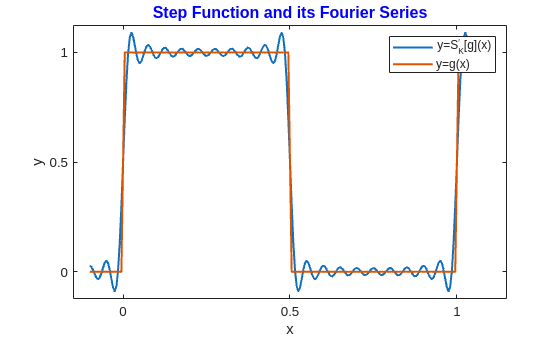

x1 = -0.1 : 0.005 : 1.1;
g = heaviside(x1+1).*heaviside(1/2-x1-1)+heaviside(x1).*heaviside(1/2-x1)+heaviside(x1-1).*heaviside(1/2-x1+1);
M2=40;
K =10;
S2=ones(M2+1,241)/2;
for k=2:M2+1
    for l=1:241
        S2(k,l)=S2(k-1,l)+2*sin(2*(2*k-3)*pi*x1(1,l))/(2*k-3)/pi;
    end
end

plot(x1,S2(K+1,:),x1,g,'LineWidth',1.5)
%axis equal
ylim([-1/8 9/8])
xlim([-0.15 1.15])
title('Step Function and its Fourier Series','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
yticks([0 1/2 1])
ylabel('y')
legend('y=S^\prime_K[g](x)','y=g(x)','Location','northeast')

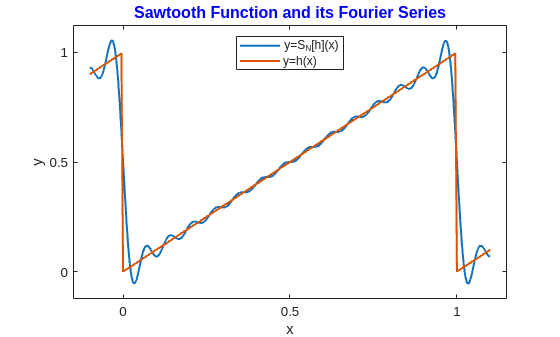

x2 = -0.1 : 0.005 : 1.1;
h = x2-floor(x2);
M3=50;
N =14;
S3=ones(M3+1,241)/2;
for n=2:M3+1
    for l=1:241
        S3(n,l)=S3(n-1,l)-sin(2*(n-1)*pi*x2(1,l))/(n-1)/pi;
    end
end

plot(x2,S3(N+1,:),x2,h,'LineWidth',1.5)
%axis equal
ylim([-1/8 9/8])
xlim([-0.15 1.15])
title('Sawtooth Function and its Fourier Series','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
yticks([0 1/2 1])
ylabel('y')
legend('y=S_N[h](x)','y=h(x)','Location','north')

## 9. Decomposition of Piecewise Smooth Functions

Finally we consider piecewise smooth $1$-periodic functions $f(x)$ on $\mathbb{R}$, that is, 

- $f(x+1)=f(x)$ for all $x\in\mathbb{R}$.

- There exist numbers $0=a_0<a_1<\cdots<a_m=1$ such that $f(x)$ is continuously differentiable on each $(a_{j-1},a_j)$, $j=1,\ldots,m$, and limits exist:


$$f(a_0+0), 
\quad
f(a_1-0),
\quad
f(a_1+0),
\quad
\ldots
\quad
f(a_m-0),$$



$$f^\prime(a_0+0), 
\quad
f^\prime(a_1-0),
\quad
f^\prime(a_1+0),
\quad
\ldots
\quad
f^\prime(a_m-0).$$


We remark that if we restrict $f(x)$ on each closed interval $[a_{j-1}+k,a_j+k]$ for $j=1,\ldots,m$ and $k\in\mathbb{Z}$, $f(x)$ can be regarded as a continuously differentiable function. We can split $f(x)$ into a Lipshitz continuous function, some step functions, and a sawtooth function. We shall illustrate this for a simplest example. 

Let $f(x)$ be a piecewise smooth $1$-periodic functions on $\mathbb{R}$ with discontinuities at most $0, c, 1$ in the interval $[0,1]$ with some $c\in(0,1)$. Note that $f(0\pm0)=f(1\pm0)$. We denote by $\chi_{[c,1]}(x)$ the characteristic function of the interval $[c,1]$. We define $f_0(x)$, $f_1(x)$, and $f_2(x)$ by 


$$f_0(x)
=
f(x)-f_1(x)-f_2(x),$$



$$f_1(x)
:=
\bigl(f(c+0)-f(c-0)\bigr)
\chi_{[c,1]}(x),$$



$$f_2(x)
=
-
\bigl\{
\bigl(f(0+0)-f(0-0)\bigr)
+
\bigl(f(c+0)-f(c-0)\bigr)
\bigr\}
h(x).$$


Then $f_0(x)$ is Lipshitz continuous. So the piecewise smooth function $f(x)$ is splitted into the Lipshitz function part $f_0(x)$, the step function part $f_1(x)$, and the sawtooth function part $f_2(x)$. From the view point of Fourier series, $f_0(x)$ is harmless, and $f_1(x)+f_2(x)$ contains discontinuities where the Gibbs phenomenon occurs. 

We illustrate this decomposition visually. 

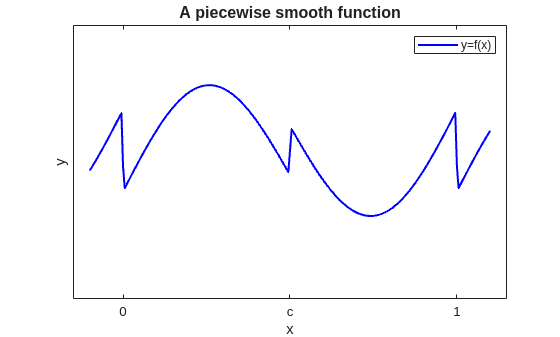

x3 = -0.1 : 0.005 : 1.1;
chi=heaviside(x3-1/2).*heaviside(1-x3)+heaviside(x3+1-1/2).*heaviside(-x3)+heaviside(x3-3/2).*heaviside(2-x3);
lin=x3-floor(x3);
F=sin(2*pi*x3)+chi/2+lin/3;

plot(x3,F,'LineWidth',1.5,color='blue')
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('A piecewise smooth function','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([])
ylabel('y')
legend('y=f(x)','Location','northeast')

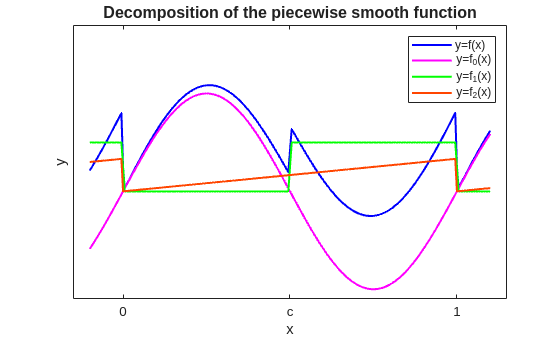

close;
F1=chi/2;
F2=lin/3;
F0=F-F1-F2;

figure;
plot(x3,F,'LineWidth',1.5,color='blue')
hold on
plot(x3,F0,'LineWidth',1.5,color='magenta')
plot(x3,F1,'LineWidth',1.5,color='green')
plot(x3,F2,'LineWidth',1.5,color="#FF4500")
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('Decomposition of the piecewise smooth function','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([])
ylabel('y')
legend('y=f(x)','y=f_0(x)','y=f_1(x)','y=f_2(x)','Location','northeast')

## **10. Weyl's equidistribution theorem**

Let $\lfloor{x}\rfloor$ be the floor function for $x\in\mathbb{R}$, that is, $\lfloor{x}\rfloor:=\max\{m \in \mathbb{Z} : m \leq x\}$, and set $\langle{x}\rangle:=x-\lfloor{x}\rfloor.$

Then $0\leq\langle{x}\rangle<1$ and $x\equiv\langle{x}\rangle$ mod $1$.

We say that a sequence $\{a_n\}_{n=1}^\infty \subset [0,1)$ is equidistributed in $[0,1)$ if 


$$\frac{\#\{n=1,\dots,N : a<a_n<b\}}{N} \rightarrow b-a \quad (N \rightarrow \infty)$$


**Weyl's equidistribution theorem**: For any $\gamma\in\mathbb{R}\setminus\mathbb{Q}$, $\{\langle{n\gamma}\rangle\}_{n=1}^\infty$ is equidistributed in $[0,1)$.

We observe Weyl's equidistribution theorem using a bijection 


$$[0,1)\ni\langle{x}\rangle \mapsto e^{2\pi{i}\langle{x}\rangle}=e^{2\pi{i}x} \in \mathbb{S}^1:=\{z\in\mathbb{C} : |z|=1\}.$$


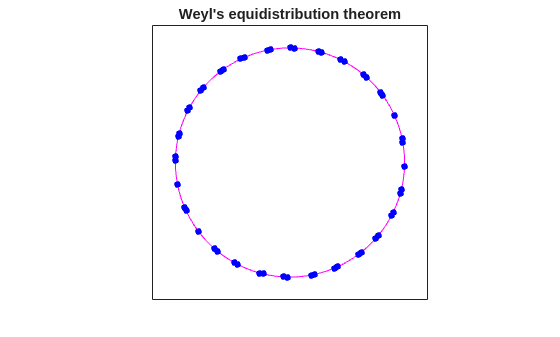

close;
MWeyl=300;
N1 =52; gammasquare =12;

t10 = 0: 0.01: 1;
c1=cos(2*pi*t10);
c2=sin(2*pi*t10);

gamma=sqrt(gammasquare);
x10=zeros(1,MWeyl);
y10=zeros(1,MWeyl);

for n=1:MWeyl
    x10(1,n)=cos(2*pi*gamma*n);
    y10(1,n)=sin(2*pi*gamma*n);
end

figure;
plot(c1,c2,'Color','magenta')
title("Weyl's equidistribution theorem")
pbaspect([1 1 1])
xlim([-1.2,1.2])
ylim([-1.2,1.2])
xticks([ ])
yticks([ ])
hold on
scatter(x10(1,1:N1),y10(1,1:N1),25,"filled","blue")

## **11. Continuous but nowhere differentiable functions**

For any $\alpha \in (0,1)$ we set 


$$f_\alpha(x):=\sum_{n=0}^\infty\frac{\exp(2\pi i2^nx)}{2^{n\alpha}}.$$


The right hand side of the above converges uniformly since $2^\alpha>1$, and $f_\alpha$ becomes a $1$-periodic continuous function on $\mathbb{R}$. To show the graph of $f_\alpha$ below, set


$$S_{\alpha,N}(x):=\sum_{n=0}^N\frac{\exp(2\pi i2^nx)}{2^{n\alpha}}.$$


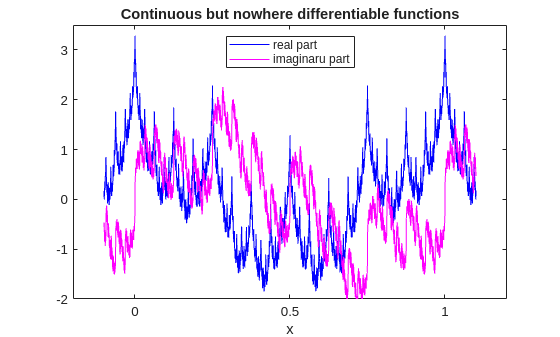

close;
M6=20;

N =12;  alpha = 0.4;

x6 = -0.1: 0.0005: 1.1;
	
f6 = zeros(length(x6),M6+1);
g6 = zeros(length(x6),M6+1);

for l=1:length(x6)
	f6(l,1)=cos(2*pi*x6(l));
	g6(l,1)=sin(2*pi*x6(l));
	for n=2:M6+1
		f6(l,n) = f6(l,n-1) + cos(2*pi*(2^n)*x6(l))/(2^(alpha*n));
		g6(l,n) = g6(l,n-1) + sin(2*pi*(2^n)*x6(l))/(2^(alpha*n));
	end
end

figure;
plot(x6,f6(:,N+1),"Color","blue")
title("Continuous but nowhere differentiable functions")
ylim([-2,3.5])
xticks([0 1/2 1])
xlabel("x")
yticks([-2 -1 0 1 2 3])
hold on
plot(x6,g6(:,N+1),"Color","magenta")
legend('real part','imaginaru part','Location','north')

## **12. The Nyquist–Shannon sampling theorem and aliasing**

We state the Nyquist-Shannon sampling theorem and observe an example. This is basically concerned with one-variable integrable functions whose Fourier transforms are compactly supported. Such functions are automatically real analytic and can be extended to entire functions on $\mathbb{C}$. We employ the definition of Fourier transform as follows. For an appropriate one-variable function $f(x)$, its Fourier transform is defined by 


$$\hat{f}(\xi)
:=
\frac{1}{\sqrt{2\pi}}
\int_{-\infty}^\infty
e^{-ix\xi}
f(x)
dx,
\quad
\xi\in\mathbb{R}.$$


We use the normalized sinc function defined by 


$$\text{sinc}(x)
:=
\frac{\sin(\pi x)}{\pi x}
\quad
(x\ne0),
\quad
\text{sinc}(0)
:=1.$$


### **Theorem (the Nyquist-Shannon sampling theorem)**

Let $B>0$. Suppose that $f(x)$ is an integrable smooth functions on $\mathbb{R}$ and $\hat{f}(\xi)=0$ for $\lvert\xi\rvert \geqq B$. Then for any $s\in(0,\pi/B]$, we have 


$$f(x)
=
\sum_{n=-\infty}^\infty
f(sn)\cdot\text{sinc}\left(\frac{x}{s}-n\right),$$



$$\int_{-\infty}^\infty
|f(x)|^2
dx
=
s
\sum_{n=-\infty}^\infty
|f(sn)|^2.$$


The parameter $s>0$ is said to be the sampling period. 

### **Observation: sampling and aliasing**

Let $f(x)$ be a function defined by 


$$f(x)
:=
\frac{2\bigl(1-\cos(\pi x)\bigr)}{(\pi x)^2}
\quad
(x\ne0),
\qquad
f(0):=1.$$


Then 


$$\hat{f}(\xi)
=
\frac{\sqrt{2}(\pi-|\xi|)}{\pi^{3/2}}
\quad
(|xi|<\pi),
\qquad
\hat{f}(\xi)=0
\quad
(|\xi|\geq\pi).$$


If we set 


$$F(x;s):=
\sum_{-\infty}^\infty
f(sn)
\cdot
\text{sinc}\left(\frac{x}{s}-n\right),
\quad
s>0,$$


then the Nyquist–Shannon Sampling Theorem implies that 


$$f(\cdot)=F(\cdot;s), \quad s\in(0,1],$$



$$f(\cdot){\ne}F(\cdot;s), \quad s>1,$$


The latter one is said to be aliasing.

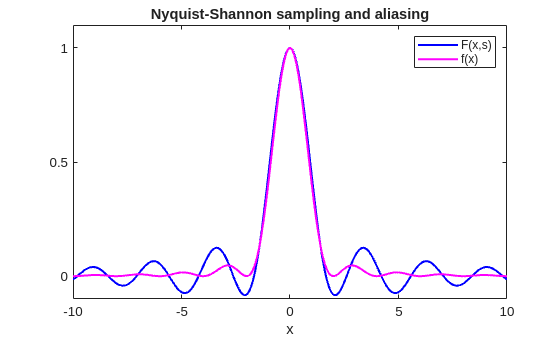

close;
s =1.4;

x20 = -10: 0.1: 10; 
F20 = sinc(x20/s);
f20=ones(1,length(x20));

for k=1:100
	f20(1,k)=2*(1-cos(pi*x20(k)))/(pi*x20(k))^2;
	f20(1,k+101)=2*(1-cos(pi*x20(k+101)))/(pi*x20(k+101))^2;
end
	
for n=1:20
	a=2*(1-cos(pi*n*s))/(pi*n*s)^2;
    b=sinc(x20/s-n*ones(1,length(x20)));
    c=sinc(x20/s+n*ones(1,length(x20)));
    F20=F20+a*b+a*c;
end

plot(x20,F20,"LineWidth",1.5,"Color","blue")
title("Nyquist-Shannon sampling and aliasing")
ylim([-0.1,1.1])
yticks([0 0.5 1])
xlabel("x")
hold on
plot(x20,f20,"LineWidth",1.5,"Color","magenta")
legend('F(x,s)','f(x)','Location','northeast')